clear all; close all;
q1=0; q2=0; q3=0; q4=0; q5=0; q6=0;
Q=[q1,q2,q3,q4,q5,q6];
L1=0.265; L2=0.444; L3=0.110; L4=0.470; L5=0.080; L6=0.101;

L(1) = Link('revolute','alpha', 0,    'a', 0,   'd',L1,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(2) = Link('revolute','alpha', -pi/2,    'a', 0,   'd',0,   'offset', -pi/2,   'modified', 'qlim',[-pi pi]);
L(3) = Link('revolute','alpha', 0,    'a', L2,   'd',0,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(4) = Link('revolute','alpha', -pi/2,    'a', L3,   'd',L4,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(5) = Link('revolute','alpha', pi/2,    'a', 0,   'd',0,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(6) = Link('revolute','alpha', -pi/2,    'a', L5,   'd',L6,   'offset', 0,   'modified', 'qlim',[-pi pi]);

plot_options = {'workspace',[-10 10 -10 10 -10 10],'scale',0.05, 'view',[45 70]};
Robot_ABB = SerialLink(L,'name','ABB CRB 15000','plotopt',plot_options);
bob = SerialLink(Robot_ABB,'name','bob');


N=15;
theta = linspace(pi/2,3*pi/2,N);
theta2 = linspace(0+deg2rad(10),pi+deg2rad(10),N);

figure(1);
hold on;
trplot(eye(4), 'width',2,'arrow');
axis([-1 1 -1 1 -1.5 1.5]);
Robot_ABB.plot([0 0 0 0 0 0],'lightpos',[2 1 1])
Robot_ABB.teach([0 0 0 0 0 0])

hold on

xlabel('X');
ylabel('Y');
zlabel('Z');
title('Espacio de trabajo');


for i=1:length(theta)
    for j = 1:length(theta2)
        TR=Robot_ABB.fkine([theta(i) theta2(j) -pi/2 0 0 0]);
        SURF1(i+1,j+1,:)=TR(:,4);
    end
end

surf(SURF1(:,:,1),SURF1(:,:,2),SURF1(:,:,3))
hold off




F=15;
theta3 = linspace(pi/2+deg2rad(11),3*pi/2+deg2rad(11),F);
theta4 = linspace(0,pi,F);

figure(2);
hold on;
trplot(eye(4), 'width',2,'arrow');
axis([-1 1 -1 1 -1.5 1.5]);
Robot_ABB.plot([0 0 0 0 0 0],'lightpos',[2 1 1])
Robot_ABB.teach([0 0 0 0 0 0])

hold on
hold off;

xlabel('X');
ylabel('Y');
zlabel('Z');
title('Espacio de trabajo');


for i=1:length(theta3)
    for j = 1:length(theta4)
        TR=Robot_ABB.fkine([theta4(j) theta3(i) -pi/2 0 0 0]);
        SURF1(i+1,j+1,:)=TR(:,4);
    end
end

surf(SURF1(:,:,1),SURF1(:,:,2),SURF1(:,:,3))
hold on



Calibracion del robot respecto los puntos:

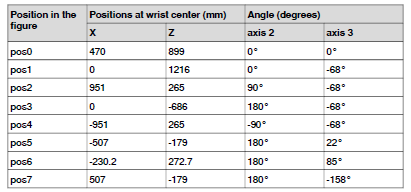

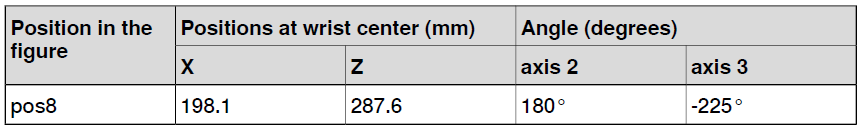

clear all; close all;
q1=0; q2=0; q3=0; q4=0; q5=0; q6=0;
Q=[q1,q2,q3,q4,q5,q6];
L1=0.265; L2=0.444; L3=0.110; L4=0.470; L5=0.080; L6=0.0;

L(1) = Link('revolute','alpha', 0,    'a', 0,   'd',L1,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(2) = Link('revolute','alpha', -pi/2,    'a', 0,   'd',0,   'offset', -pi/2,   'modified', 'qlim',[-pi pi]);
L(3) = Link('revolute','alpha', 0,    'a', L2,   'd',0,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(4) = Link('revolute','alpha', -pi/2,    'a', L3,   'd',L4,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(5) = Link('revolute','alpha', pi/2,    'a', 0,   'd',0,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(6) = Link('revolute','alpha', -pi/2,    'a', L5,   'd',L6,   'offset', 0,   'modified', 'qlim',[-pi pi]);

plot_options = {'workspace',[-10 10 -10 10 -10 10],'scale',0.05, 'view',[45 70]};
Robot_ABB = SerialLink(L,'name','ABB CRB 15000','plotopt',plot_options);



(En metros)

Para la posición 0:


TR0=Robot_ABB.fkine([0 0 0 0 0 0]);
P0 = TR0(:,4);
x0 = P0(1)
z0 = P0(3)

Para la posición 1:


TR1=Robot_ABB.fkine([0 0 -deg2rad(68) 0 0 0]); 
P1 = TR1(:,4);
x1 = P1(1)
z1 = P1(3)

Para la posición 2:


TR2=Robot_ABB.fkine([0 pi/2 -deg2rad(68) 0 0 0]); %-deg2rad(68)
P2 = TR2(:,4);
x2 = P2(1)
z2 = P2(3)

Para la posición 3:


TR3=Robot_ABB.fkine([0 pi -deg2rad(68) 0 0 0]); %-deg2rad(68)
P3 = TR3(:,4);
x3 = P3(1)
z3 = P3(3)

Para la posición 4:


TR4=Robot_ABB.fkine([0 -pi/2 -deg2rad(68) 0 0 0]); %-deg2rad(68)
P4 = TR4(:,4);
x4 = P4(1)
z4 = P4(3)

Para la posición 5:


TR5=Robot_ABB.fkine([0 pi deg2rad(22) 0 0 0]); %-deg2rad(68)
P5 = TR5(:,4);
x5 = P5(1)
z5 = P5(3)

Para la posición 6:


TR6=Robot_ABB.fkine([0 pi deg2rad(85) 0 0 0]); %-deg2rad(68)
P6 = TR6(:,4);
x6 = P6(1)
z6 = P6(3)

Para la posición 7:


TR7=Robot_ABB.fkine([0 pi -deg2rad(158) 0 0 0]); %-deg2rad(68)
P7 = TR7(:,4);
x7 = P7(1)
z7 = P7(3)

Para la posición 8:


TR8=Robot_ABB.fkine([0 pi -deg2rad(225) 0 0 0]); %-deg2rad(68)
P8 = TR8(:,4);
x8 = P8(1)
z8 = P8(3)